## Validation of the S3

Loyal Murphy

September 18, 2022

### Information about the trial:

The following validation utilizes *Chlorella Sorokiniana* on diluted wastewater (10% filtered AD, 90% clarifier water). In this test, all 9 S3 vials were run simulaneously with temperature set at    25$^{\circ}$C, agitation at 300 rpm, and pH control at 7.0. The reactor was provided 2.0 vol% carbon dioxide in nitrogen, with total flow rate of .22 vvm. The LED walls were adjusted to provide approximately 180 $\mu m$ photons/m^2/s to each vessel

### Initialization:

clear variables
clc

### Data:

Times = [datetime(2022,9,15,13,30,00);...
    datetime(2022,9,15,15,05,00);...
    datetime(2022,9,16,12,25,00);...
    datetime(2022,9,16,17,59,00);...
    datetime(2022,9,16,21,47,00);...
    datetime(2022,9,17,09,40,00);...
    datetime(2022,9,17,17,33,00);...
    datetime(2022,9,17,22,06,00);...
    datetime(2022,9,18,12,44,00);...
    datetime(2022,9,18,18,20,00);...
    datetime(2022,9,18,22,40,00);...
    datetime(2022,9,19,10,18,00);...
    datetime(2022,9,19,23,00,00);...
    datetime(2022,9,20,11,05,00)];

OD_readings = [0.067,0.065,0.066,0.067,0.068,0.068,0.067,0.067,0.067;...
    .125,.118,.128,.126,.124,.123,.130,.136,.126;...
    .219,.216,.243,.231,.231,.228,.263,.255,.238;...
    .376,.374,.418,.397,.396,.392,.444,.437,.391;...
    1.50,1.58,1.62,1.62,1.60,1.61,1.725,1.61,1.54;...
    2.384,2.488,2.60,2.56,2.524,2.464,2.656,2.672,2.352;...
    3.22,3.25,3.30,3.40,3.36,3.34,3.55,3.62,3.10;...
    4.80,4.995,4.875,4.89,4.92,4.95,5.295,4.95,4.815;...
    5.12,5.46,5.30,5.38,5.40,5.42,5.6,5.32,5.38;...
    5.24,5.82,5.72,5.52,5.68,5.74,6.12,5.70,5.46;...
    6.12,6.36,6.08,6.22,6.22,6.24,6.88,6.10,6.20;...
    6.38,6.92,6.50,6.58,6.65,6.76,7.20,6.60,6.88;...
    6.70,7.06,6.92,6.76,6.96,7.12,7.40,6.72,7.24];

DCW_readings = 0.39 * OD_readings;
t = hours(Times - Times(1));
t = t(2:end);
save('Soro_raw.mat',"DCW_readings","t")

### Data Transformation:

DCW_ave = mean(DCW_readings,2);
DCW_std = std(DCW_readings,0,2); %0 gives equal weight to all readings

% Save data to be used outside the code
save('Sorokiniana.mat',"DCW_ave","DCW_std","t");

### Plots:

figure()
p = plot(t,DCW_ave,'x-','Color',[0 .7 0],'MarkerSize',6);
p.LineWidth = 1.5;
hold on
err = errorbar(t,DCW_ave,-DCW_std,DCW_std);
err.Color = 'black';
err.LineStyle = 'none';
hold off
grid on;
%title('C. Sorokiniana Growth on Diluted Wastewater across Nine Vessels','(Vessels falling outside standard deviation plotted)');
xlabel('Time Elapsed (hr)','FontSize',18,'FontWeight','bold');
ylabel('[Biomass] (gDCW/L)','FontSize',18,'FontWeight','bold');
show(p);

  Line with properties:

              Color: [ + ]
          LineStyle: '-'
          LineWidth: +
             Marker: 'x'
         MarkerSize: +
    MarkerFaceColor: 'none'
              XData: [+ + + + + + + + + + + + +]
              YData: [+ + + + + + + + + + + + +]

  Show all properties




% Now, we can plot the "outliers" to see how they compare.
% The primary outliers in this dataset were Vessels 1, 7, and 9.

t_index = (t > 40);
DCW_up = DCW_ave(t_index) + DCW_std(t_index);
DCW_down = DCW_ave(t_index) - DCW_std(t_index);

DCW_read_longt = DCW_readings(t_index,:)

DCW_read_longt =     0.5850    0.6162    0.6318    0.6318    0.6240    0.6279    0.6728    0.6279    0.6006
    0.9298    0.9703    1.0140    0.9984    0.9844    0.9610    1.0358    1.0421    0.9173
    1.2558    1.2675    1.2870    1.3260    1.3104    1.3026    1.3845    1.4118    1.2090
    1.8720    1.9481    1.9013    1.9071    1.9188    1.9305    2.0650    1.9305    1.8779
    1.9968    2.1294    2.0670    2.0982    2.1060    2.1138    2.1840    2.0748    2.0982
    2.0436    2.2698    2.2308    2.1528    2.2152    2.2386    2.3868    2.2230    2.1294
    2.3868    2.4804    2.3712    2.4258    2.4258    2.4336    2.6832    2.3790    2.4180
    2.4882    2.6988    2.5350    2.5662    2.5935    2.6364    2.8080    2.5740    2.6832
    2.6130    2.7534    2.6988    2.6364    2.7144    2.7768    2.8860    2.6208    2.8236


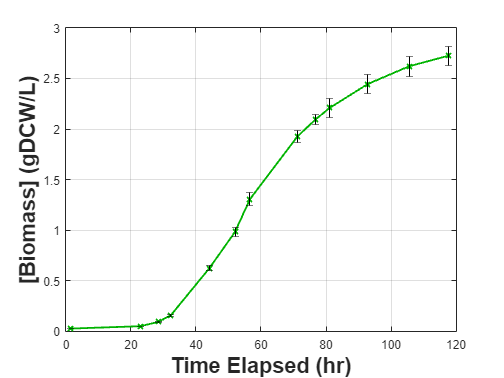

for i = 1:size(DCW_read_longt,1)
    for j = 1:size(DCW_read_longt,2)
        if (DCW_read_longt(i,j) > DCW_down(i)) && (DCW_read_longt(i,j) < DCW_up(i))
            DCW_read_longt(i,j) = nan;
        end
    end
end

% Plot the outliers onto the original plot
hold on
%plot(t(t_index),DCW_read_longt,'s','MarkerSize',8)
hold off

%legend('Average DCW','','Vessel 1','Vessel 2','','','','Vessel 7','Vessel 8','Vessel 9',...
%    'location','northwest','FontSize',12)

### Growth Rate Results:

Calculate the average growth rate and standard deviation for each individual trial; take the average and standard deviation.

g_rates = zeros(length(t),size(DCW_readings,2));
for i = 2:length(t)
    g_rates(i,:) = log(DCW_readings(i,:)./DCW_readings(i-1,:))/(t(i) - t(i-1));
end

gr_ave = mean(g_rates,2);
gr_std = std(g_rates,0,2);

Results = table(t,DCW_ave,DCW_std,DCW_std*100./DCW_ave,gr_ave,gr_std,...
    'VariableNames',{'Time Elapsed (hr)','Conc (g/L)','Conc STDev','% Difference','Average Growth Rate','Growth Rate STDev'})

Results = 13×6 table
    Time Elapsed (hr)    Conc (g/L)    Conc STDev    % Difference    Average Growth Rate    Growth Rate STDev
    _________________    __________    __________    ____________    ___________________    _________________

         1.5833           0.026087     0.0003619        1.3873                    0                     0    
         22.917           0.049227      0.001938         3.937             0.029738              0.001774    
         28.483            0.09204     0.0060826        6.6087               0.1122             0.0068691    
         32.283            0.15708      0.009732        6.1954              0.14073             0.0041772    
         44.167            0.62422      0.024129        3.8655              0.11619             0.0033609    
    

## **4Z model fit**

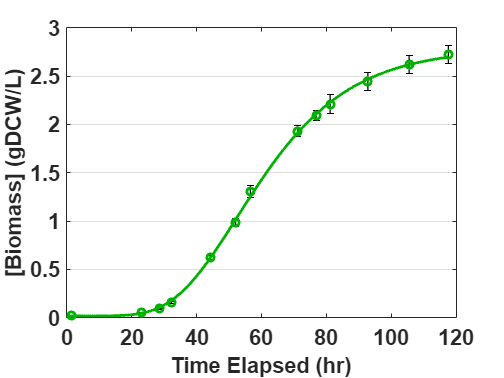

for i = 1:9
    gDCWs = DCW_readings(:,i);
    % Plot the individual data sets with their Gompertz models
    x = t;
    figure(); clf;
    Xo = gDCWs(1); %Initial biomass
    foB = fitoptions('Method','NonlinearLeastSquares','Lower',[0,0,0,0.7*Xo],'Upper',[3,0.35,100,1.3*Xo],'StartPoint',[2.7,0.2,30,Xo]);
    ft_ZMB = fittype('d + a*exp(-exp(exp(1)*b/a * (c - x) + 1))','independent',{'x'},'dependent',{'y'},'options',foB); %Zweitering
    % a = Carrying Capacity
    % b = Growth Rate
    % c = Delay Time
    % d = Vertical Shift

    % Define gDCW measurements and model predictions
    [curve_ZMB,sZMB] = fit(x,gDCWs,ft_ZMB);
    CI = confint(curve_ZMB);
    K_vals(i) = curve_ZMB.a;
    K_SE(i) = (CI(2,1)-CI(1,1))/(2*1.96);
    muR_vals(i) = curve_ZMB.b;
    m_SE(i) = (CI(2,2)-CI(1,2))/(2*1.96);
    tLAG_vals(i) = curve_ZMB.c;
    t_SE(i) = (CI(2,3)-CI(1,3))/(2*1.96);
    D_vals(i) = curve_ZMB.d;
    if isnan(CI(2,4))
        D_SE(i) = 0;
    else
        D_SE(i) = (CI(2,4)-CI(1,4))/(2*1.96);
    end
end

% Plot the Gompertz Model for the Validation
Xo = DCW_ave(1); %Initial biomass
foB = fitoptions('Method','NonlinearLeastSquares','Lower',[0,0,0,0.7*Xo],'Upper',[3,0.35,100,1.3*Xo],'StartPoint',[2.7,0.2,30,Xo]);
ft_ZMB = fittype('d + a*exp(-exp(exp(1)*b/a * (c - x) + 1))','independent',{'x'},'dependent',{'y'},'options',foB); %Zweitering
[curve_ave,s_ave] = fit(t,DCW_ave,ft_ZMB);
%figure()
subplot(1,2,2)
err = errorbar(t,DCW_ave,-DCW_std,DCW_std,'LineWidth',1);
hold on
err.Color = 'black';
err.LineStyle = 'none';
plot(t,DCW_ave,'o','Color',[0 .7 0],'MarkerSize',6,'LineWidth',2.3);
plot(linspace(0,max(t),200),curve_ave(linspace(0,max(t),200)),'-','LineWidth',2.3,'Color',[0 0.7 0])
hold off
ax = gca;
ax.FontSize = 18;
ax.FontWeight = 'bold';
xlabel('Time Elapsed (hr)','FontSize',18,'FontWeight','bold');
ylabel('[Biomass] (gDCW/L)','FontSize',18,'FontWeight','bold');
ax.XLim = [0 120];
ax.XTick = [0 20 40 60 80 100 120] ;
ax.YTick = [0 0.5 1.0 1.5 2.0 2.5 3.0] ;
ax.YGrid = 'on';


subplot(1,2,1)
% S3 Image %


table(linspace(1,9,9)',K_vals',K_SE',muR_vals',m_SE',tLAG_vals',t_SE',D_vals',D_SE','VariableNames',{'Vessel #','K','K-SE','\mu_R','\mu-SE','tLAG','t-SE','X_o','X-SE'})

ans = 9×9 table
    Vessel #      K         K-SE       \mu_R       \mu-SE       tLAG      t-SE        X_o         X-SE  
    ________    ______    ________    ________    _________    ______    _______    ________    ________

       1        2.6534    0.073843    0.050521     0.002187    33.301     1.4999    0.018291     0.03567
       2        2.8329    0.037129    0.054388    0.0011254    33.969    0.69982    0.017758    0.017646
       3        2.7078    0.056149    0.052102    0.0016983    32.745     1.1312    0.018018    0.027942
       4        2.6821    0.048808    0.052983    0.0015726    32.964    0.99647    0.018292    0.024671
       5        2.7461    0.030471    0.053162 

## Grubbs' Test

% Data independent calculations %
n = 9;
alpha = 0.05;
tcrit = abs(tinv(alpha/n,n-2)); %One-sided Grubbs Test
Gcrit = (n-1)*tcrit/sqrt(n*(n-2+tcrit^2));
disp(['Gcrit = ',num2str(Gcrit)]);

Gcrit = 2.1096



% For K
Gval_hi = (max(K_vals) - mean(K_vals))/std(K_vals)

Gval_hi = 1.7169

Gval_low = (mean(K_vals) - min(K_vals))/std(K_vals)

Gval_low = 1.0938

if Gval_hi > Gcrit
    disp('THERE IS A HIGH OUTLIER IN K_VALS');
    disp(num2str(K_vals));
elseif Gval_low > Gcrit
    disp('THERE IS A LOW OUTLIER IN K_VALS');
    disp(num2str(K_vals));
else
    disp('There is no outlier in K_vals.')
end

There is no outlier in K_vals.



% For mu_rel
Gval_hi = (max(muR_vals) - mean(muR_vals))/std(muR_vals)

Gval_hi = 1.7790

Gval_low = (mean(muR_vals) - min(muR_vals))/std(muR_vals)

Gval_low = 1.4856

if Gval_hi > Gcrit
    disp('THERE IS A HIGH OUTLIER IN mu_rel');
    disp(num2str(muR_vals));
elseif Gval_low > Gcrit
    disp('THERE IS A LOW OUTLIER IN mu_rel');
    disp(num2str(muR_vals));
else
    disp('There is no outlier in mu_rel.')
end

There is no outlier in mu_rel.



% For T_lag
Gval_hi = (max(tLAG_vals) - mean(tLAG_vals))/std(tLAG_vals)

Gval_hi = 1.8422

Gval_low = (mean(tLAG_vals) - min(tLAG_vals))/std(tLAG_vals)

Gval_low = 1.5540

if Gval_hi > Gcrit
    disp('THERE IS A HIGH OUTLIER IN tLAG_VALS');
    disp(num2str(tLAG_vals));
elseif Gval_low > Gcrit
    disp('THERE IS A LOW OUTLIER IN tLAG_VALS');
    disp(num2str(tLAG_vals));
else
    disp('There is no outlier in tLAG_vals.')
end

There is no outlier in tLAG_vals.



% For Xo
Gval_hi = (max(D_vals) - mean(D_vals))/std(D_vals)

Gval_hi = 1.2054

Gval_low = (mean(D_vals) - min(D_vals))/std(D_vals)

Gval_low = 2.0177

if Gval_hi > Gcrit
    disp('THERE IS A HIGH OUTLIER IN tLAG_VALS');
    disp(num2str(D_vals));
elseif Gval_low > Gcrit
    disp('THERE IS A LOW OUTLIER IN tLAG_VALS');
    disp(num2str(D_vals));
else
    disp('There is no outlier in tLAG_vals.')
end

There is no outlier in tLAG_vals.
